# Principal Component Analysis (PCA)-In MATLAB

%Let's view some few rows of the data
digits=csvread('digits.csv');
digits

digits =      0     0     5    13     9     1     0     0     0     0    13    15    10    15     5     0     0     3    15     2     0    11     8     0     0     4    12     0     0     8     8     0     0     5     8     0     0     9     8     0     0     4    11     0     1    12     7     0     0     2
     0     0     0    12    13     5     0     0     0     0     0    11    16     9     0     0     0     0     3    15    16     6     0     0     0     7    15    16    16     2     0     0     0     0     1    16    16     3     0     0     0     0     1    16    16     6     0     0     0     0
     0     0     0     4    15    12     0     0     0     0     3    16    15    14     0     0     0     0     8    13     8    16     0     0     0     0     1     6    15    11     0     0     0     1     8    13    15     1     0     0     0     9    16    16     5     0     0     0     0     3
     0     0     7    15    13     1     0     0     0     8    13     6    15     4    

% Asign names to the measurements and target variable
% X represents the matrix of pixels of the images
% Y represents the vector of labels of the images
X = digits(:,1:end-1);
Y = digits(:,end);

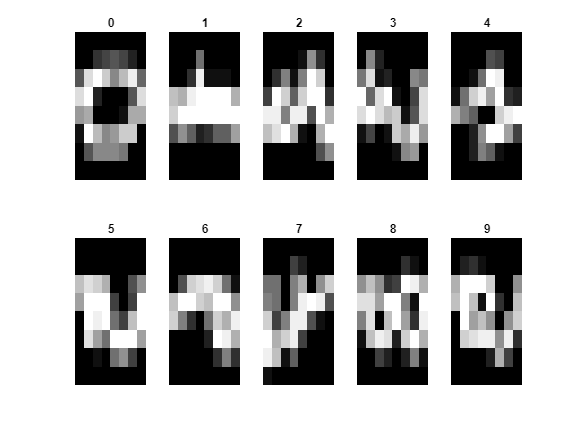

%plots the first ten digits
for i = 1:10
    %creates a subplot
    subplot(2, 5, i)
    %reshapes the image
    rs=reshape(X(i,:), 8, 8);
    %rearanges the reshaped matrix
    imagesc(rs)
    colormap gray
    title(num2str(Y(i)))
    axis off
end

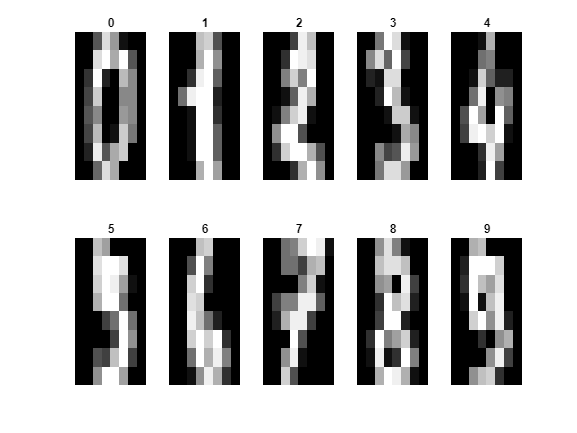

%ploting the first ten digits again
for i = 1:10
    %create a subplot
    subplot(2, 5, i)
    %reshape the image
    rs=reshape(X(i,:), 8, 8);
    %rearange the reshaped matrix
    rsa=rs(:,end:-1:1);
    %show the image
    imagesc(imrotate(rsa,90))
    colormap gray
    title(num2str(Y(i)))
    axis off
end

%this scatterPlot function takes in a table as argument, so we need to covert 
% the first 3 columns of matrix x into a table 
Xt=array2table(X(:,1:4));
%figure,sdo.scatterPlot(Xt)

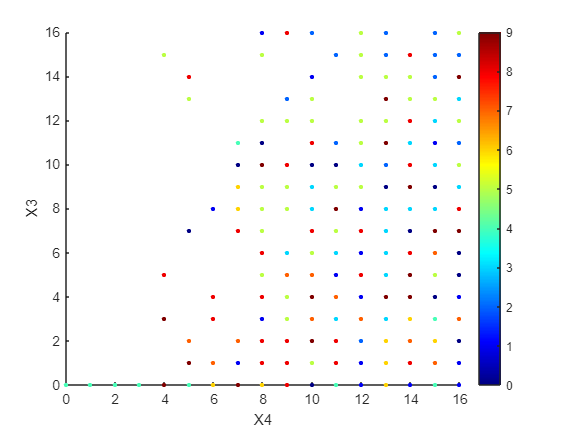

figure,scatter(X(:,4), X(:,3),10,Y,"filled")
colormap("jet");
colorbar;
xlabel('X4'),ylabel("X3")

#### 4.1 PCA with the eigen Decomposition function

%Stardardize the measurements in X
% Since the column of the digit dataset are on the same scale there is no
% need to standardize but if there is a need to stardardize, use the
% following commented code
    % X_standard = zscore(X); % or
    % X_standard = (X-mean(X))./std(X);

%we only need to center the data
X_standard = X-mean(X);

%Compute the covariance matrix
cov_matrix = cov(X_standard);

% Compute the eigenvectors and eigenvalues
[eigenVectors, eigenValues]=eig(cov_matrix);

% Sort the eigenvalues and eigenvectors in descending order
[eigenValues, order]=sort(diag(eigenValues),'descend'); 
eigenVectors = eigenVectors(:,order);

% Select the number of components to keep
num_components=2;
eigenVectors_ = eigenVectors(:, 1:num_components);

%Project the data onto the principal components
projected_data = X_standard * eigenVectors_;

Lets make a scatter plot with the projected data

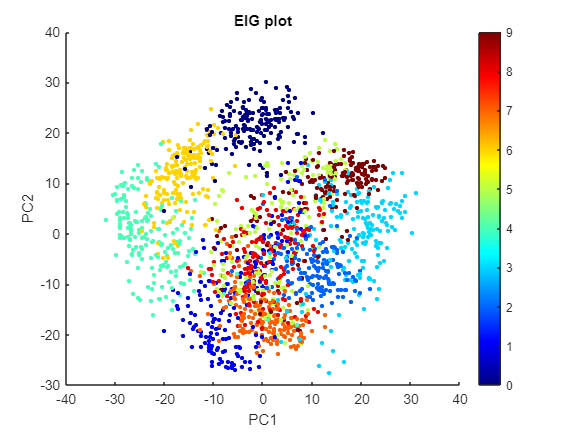

figure,scatter(projected_data(:,1), projected_data(:,2),10,Y,"filled")
colormap("jet");
colorbar;
xlabel('PC1'),ylabel("PC2")
title('EIG plot')

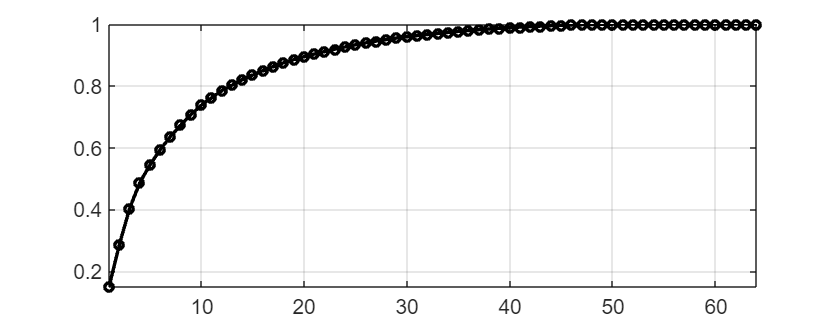

%calculate a cumulative sum of the sorted eigen values
cumsum_=cumsum(eigenValues);

%sum all the sorted eigen values
sum_=sum(eigenValues);

%calculate the percentages of variance expalined by the first n principal components
pvex= cumsum_./sum_;

%plot the percentage
figure,plot(pvex, 'k-o','Linewidth' ,2.5)
set(gca,'FontSize', 15), axis tight, grid on
set(gcf, 'Position',[1400 100 3*650 3*250])

#### 4.2 PCA with the SVD Decomposition function

X_standard = X-mean(X);

%Compute the covariance matrix
cov_matrix = cov(X_standard);

% Compute the eigenvectors and eigenvalues
[U, Sigma, V]=svd(cov_matrix);

% Select the number of components to keep
num_components=2;
eigenVectors_ = V(:, 1:num_components);

%Project the data onto the principal components
projected_data = X_standard * eigenVectors_;

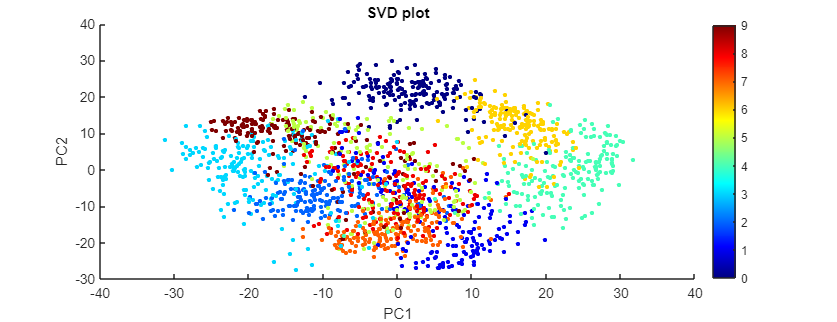

scatter(projected_data(:,1), projected_data(:,2),10,Y,"filled")
colormap("jet");
colorbar;
xlabel('PC1'),ylabel("PC2")
title('SVD plot')

%calculate a cumulative sum of the sorted eigen values
cumsum_=cumsum(diag(Sigma));

%sum all the sorted eigen values
sum_=sum(diag(Sigma));

%calculate the percentages of variance expalined by the first n principal components
pvex= cumsum_./sum_;

%plot the percentage
figure,plot(pvex, 'k-o','Linewidth' ,2.5)
set(gca,'FontSize', 15), axis tight, grid on
set(gcf, 'Position',[1400 100 3*650 3*250])

#### 4.2 PCA with the PCA  function

% Perform PCA
[coeff, score, latent]=pca(X);

% Select the number of components to keep
num_components=2;

% Project the data onto the principal components
% since we are using the pca function, the projected data is just the
% selected number of components of our score
projected_data = score(:,1:num_components);

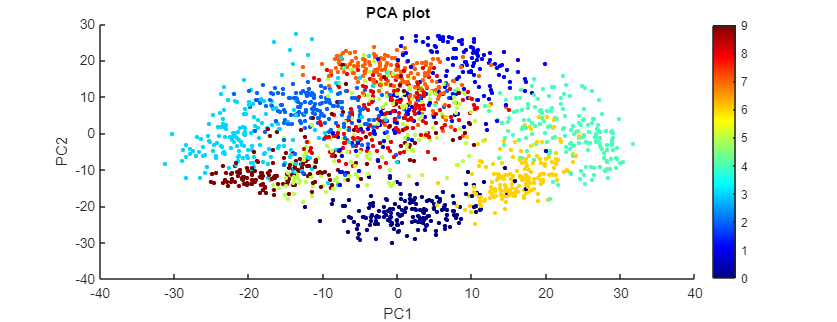

scatter(projected_data(:,1), projected_data(:,2),10,Y,"filled")
colormap("jet");
colorbar;
xlabel('PC1'),ylabel("PC2")
title('PCA plot')

%calculate a cumulative sum of the sorted eigen values
cumsum_=cumsum(latent);

%sum all the sorted eigen values
sum_=sum(latent);

%calculate the percentages of variance expalined by the first n principal components
pvex= cumsum_./sum_;

%plot the percentage
figure,plot(pvex, 'k-o','Linewidth' ,2.5)
set(gca,'FontSize', 15), axis tight, grid on
set(gcf, 'Position',[1400 100 3*650 3*250])